clear
clf
clc
f0 = 30 * 10^6;
fs = 200*10^6;
tmax = 0.1;
ts = [0:1/fs:tmax];
Tc = 1.023 * 10^6;

chipNum = floor(ts*Tc)+1;
prncode = randi([0 1],1,chipNum(end));
prncode = prncode*2 -1;



carrier_wave = sin(f0*ts*(2*pi));
prnSampled = prncode(chipNum) .* carrier_wave;
%plot(ts(1:1000),prnSampled(1:1000))

%task 2
psd_carrier = pwelch(carrier_wave);
psd_ca = pwelch(prnSampled);

psd_carrier_filtered = filtfilt(ones(1,500),1,psd_carrier);
psd_carrier_db = mag2db(psd_carrier);

psdfiltered_ca = filtfilt(ones(1,500),1,psd_ca);
psdfilteredlog_ca = mag2db(psdfiltered_ca);
%figure()
%plot(psdfiltered_ca)
%hold on
%plot(psd_carrier_db)


%task 3
Tc_P = 10.23 *10^6;
chipNum_P = floor(ts*Tc_P)+1;
prncode_P = randi([0 1],1,chipNum_P(end))*2 -1;

prnSampled_P = prncode_P(chipNum_P) .* carrier_wave;
prnSampled_P = prnSampled_P/sqrt(2);
%figure()
%plot(ts(1:1000),prnSampled_P(1:1000))
psd_P = pwelch(prnSampled_P);
psdfiltered_P = filtfilt(ones(1,500),1,psd_P);
psdfilteredlog_P = mag2db(psdfiltered_P);


%task 4
M_carrier = square(ts*2*pi*10.23*10^6);
chipNum_M = floor(ts*5*1.023*10^6)+1;
M_prn = randi ([0 1], 1,chipNum_M(end))*2 -1;
M_sampled = M_prn(chipNum_M).*M_carrier.*carrier_wave;
%figure()
%plot(ts(1:1000),M_sampled(1:1000))
psd_M = pwelch(M_sampled);
psdfiltered_M = filtfilt(ones(1,500),1,psd_M);
psdfilteredlog_M = mag2db(psdfiltered_M);

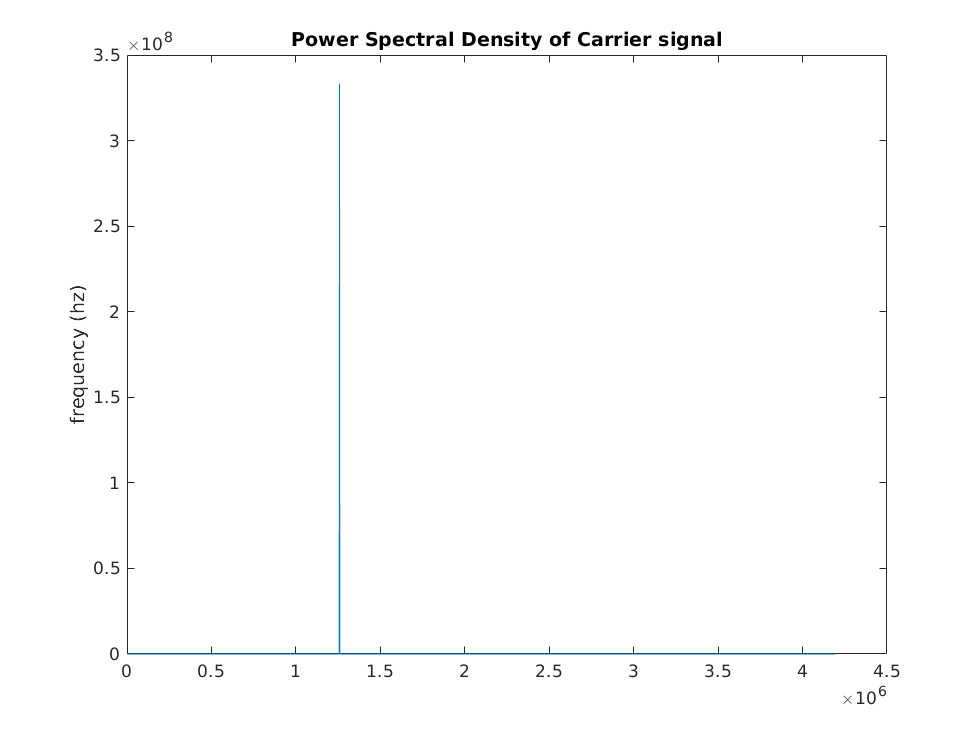

%turn in
figure()
plot(psd_carrier_filtered)
title("Power Spectral Density of Carrier signal")
ylabel("frequency (hz)")

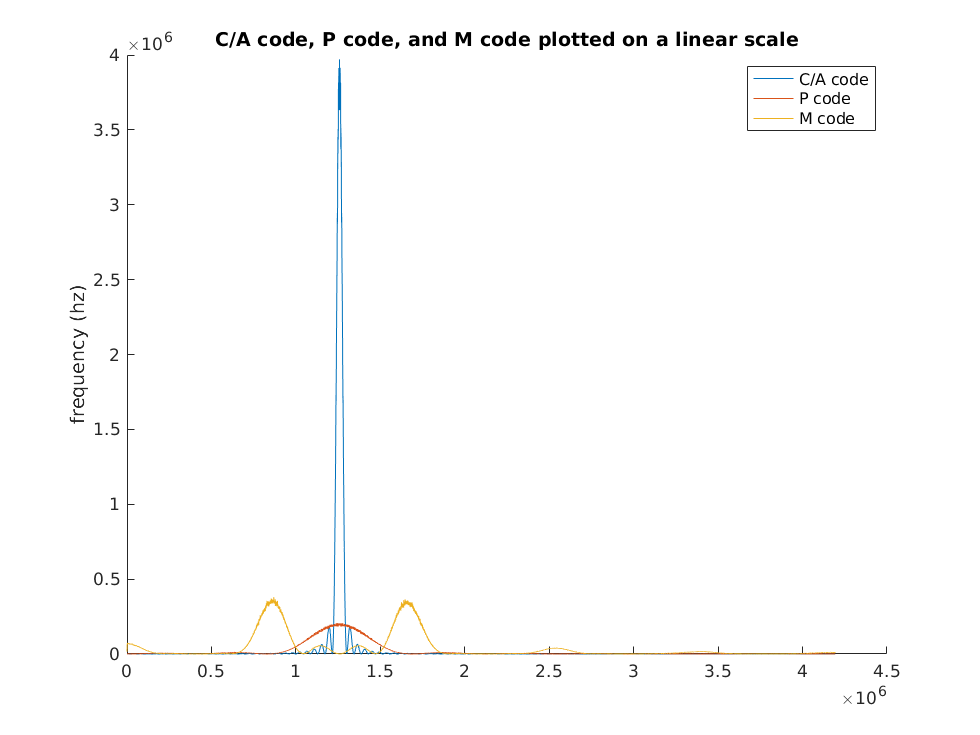


figure()
hold on
plot (psdfiltered_ca)
plot(psdfiltered_P)
plot(psdfiltered_M)
legend("C/A code","P code", "M code")
title("C/A code, P code, and M code plotted on a linear scale")
ylabel("frequency (hz)")

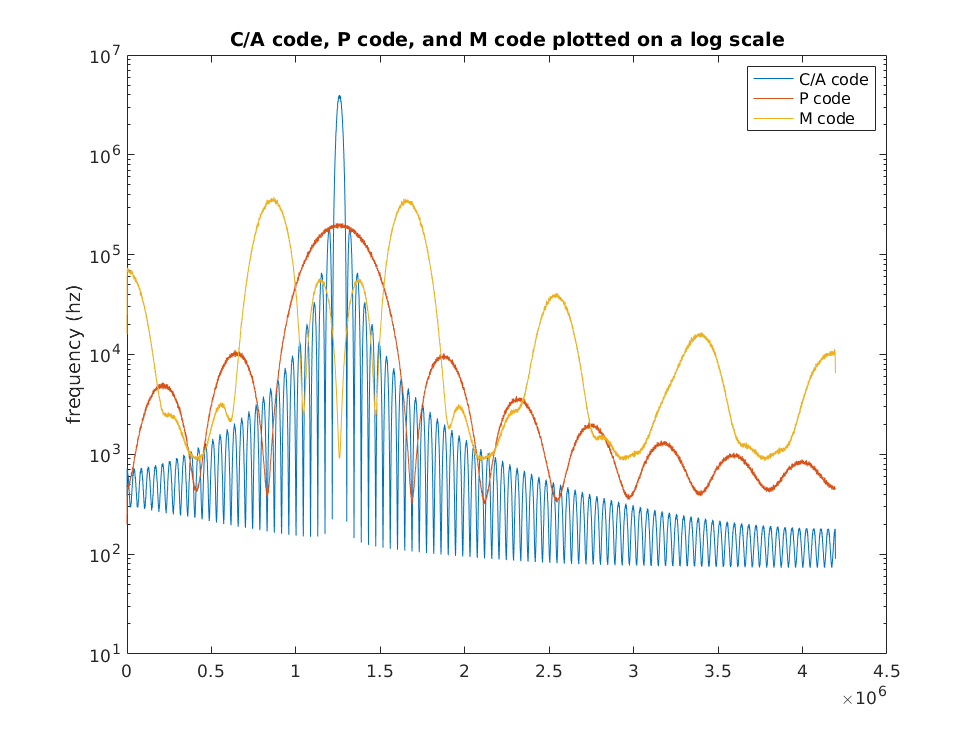



figure()
semilogy (psdfiltered_ca)
hold on
semilogy(psdfiltered_P)
semilogy(psdfiltered_M)
legend("C/A code","P code", "M code")
title("C/A code, P code, and M code plotted on a log scale")
ylabel("frequency (hz)")